clear; close all;

rng(100)
X1 = mvnrnd([1 3],[1 0; 0 1],60); X2 = mvnrnd([4 1],[2 0; 0 2],40);
X = [X1; X2];

y1 = ones(size(X1,1),1); y2 = -ones(size(X2,1),1);
y = [y1; y2];

feature = size(X,2);
N = size(X,1);
C = 0.1;

Kernel = X*X';
yy = y*y';
H = (yy.*(Kernel));
f = -ones(1, N);
A = zeros(1,N);
b = 0;
Aeq = y';
beq = 0;
lb = zeros(N,1);
ub = C*ones(N,1);

lamda = quadprog(H,f,A,b,Aeq,beq,lb,ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


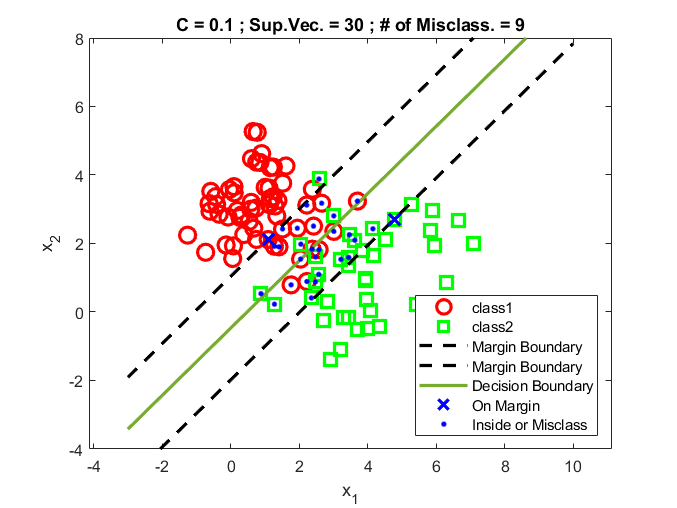

SV = find(lamda>0.001); 
nSV = numel(SV);
SV_1 = find(lamda < (C*0.99) & lamda>0.001);
SV_2 = find(lamda > (C*0.99));

w = [0 0];
for i = 1 : N
    w = w+lamda(i)*y(i)*X(i,:);
end

w0 = 0;
for i = 1 : numel(SV_1)
    w0 = w0 + 1/y(SV_1(i)) - w*X(SV_1(i),:)';    
end
w0 = w0/numel(SV_1);

misclass = 0;
for i=1 : N
    if (w*X(i,:)'+w0) * y(i) <= 0
        misclass = misclass + 1;
    end
end
    
% plotting
range = -3:0.0001:10;
d = (w(1)*range+w0)/-w(2);
d1 = (-w(1)*range-w0+1)/w(2);
d2 = (-w(1)*range-w0-1)/w(2);

figure;
plot(X1(:,1),X1(:,2), 'or',...
    X2(:,1),X2(:,2), 'sg',...
    range,d1, '--k',...
    range,d2, '--k',...
    range,d,...
    X(SV_1,1),X(SV_1,2), 'bx',...
    X(SV_2,1),X(SV_2,2), 'b.',...
    'LineWidth',2,...
    'MarkerSize', 10);
axis equal
title(['C = ', num2str(C),' ; Sup.Vec. = ',num2str(nSV), ' ; # of Misclass. = ', num2str(misclass)]);
legend({'class1','class2',...
    'Margin Boundary','Margin Boundary','Decision Boundary',...    
    'On Margin', 'Inside or Misclass'},'Location','southeast')
xlabel('x_{1}'); ylabel('x_{2}');

ylim([-4 8]);

fitcsvm(X,y,"BoxConstraint",C)

ans =   ClassificationSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [-1 1]
           ScoreTransform: 'none'
          NumObservations: 100
                    Alpha: [30×1 double]
                     Bias: 0.3125
         KernelParameters: [1×1 struct]
           BoxConstraints: [100×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [100×1 logical]
                   Solver: 'SMO'


  Properties, Methods
